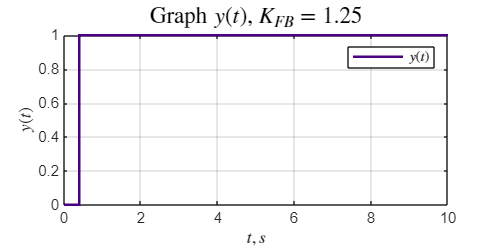

clear all;

K_CO = 4;
T = 0.2;
%K_FB = 0;
%K_FB = 2 / (T * K_CO)
K_FB = 1.25;

open_system('schem_1');
set_param('schem_1/y', 'VariableName', 'y');

out = sim('schem_1');


y_data = out.y.Data;
t_time = out.y.Time;


% Определяем цвета для линий
a_color = '#4B0082'; 
b_color = '#7B68EE';
c_color = '#800080'; 
d_color = '#0000CD';
e_color = '#EE82EE';

figure('Position', [100 100 800 400]);
stairs(t_time, y_data, '-', 'LineWidth', 1.5, 'Color', a_color);
hold on;
%plot(t_time, x_M_data(:,1), '--', 'LineWidth', 1.5, 'Color', d_color);
%plot(t_time, x_data(:,2), '-', 'LineWidth', 1.5, 'Color', e_color);
%plot(t_time, x_M_data(:,2), '--', 'LineWidth', 1.5, 'Color', c_color);

grid on;

title('Graph $y(t)$, $K_{FB} = 1.25$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$y(t)$','Interpreter', 'latex' );
xlabel('$t, s$', 'Interpreter', 'latex');
legend('$y(t)$','Interpreter', 'latex')
hold off;

full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_1\Discrete_report_1\pic\' ...
    '1_trans_min_time.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);